# Metrics

clear all; close all

## Generating random graph

n = 20; %number of edges
N = 9; %number of nodes
nmax = N*(N-1)

nmax = 72

if n >= nmax
    n = nmax;
end
edges = zeros(2,n)

edges =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%s = zeros(1,n);
%t = zeros(1,n);
for i = 1:n
    while true
        s = round(rand()*N+1);
        t = round(rand()*N+1);
        if s == t
            %checking if it is not self looping
            disp('removed self loop')
            continue
        end
        if sum(sum(edges == [s; t]) == 2) == 1 || sum(sum(edges == [t; s]) == 2) == 1
            %not checking if this edge already exist
            disp('removed dupe edge');
            continue
        end
        
        edges(:,i) = [s;t];
        
        break
    end
    
end

removed self loop


removed dupe edge
removed dupe edge


removed self loop


removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge
removed dupe edge


ans = 1×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0


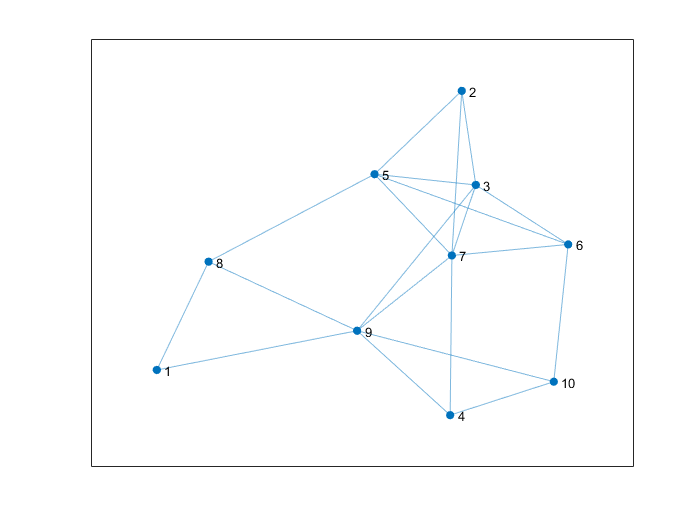

s = edges(1,:);
t = edges(2,:);

G = graph(s,t,[],N+1);
plot(G)

## Creating a randomly generated multilayer graph

N = 3; %number of nodes
n = 2; %number of edges
m = 4; %number of layers

sA = zeros(N*m,N*m); %supra matrix of A 
d = diag(ones(N,1)); %diagonal matrix

ans =      0     0     0     1     0     0     1     0     0
     0     0     0     0     1     0     0     1     0
     0     0     0     0     0     1     0     0     1
     1     0     0     0     0     0     1     0     0
     0     1     0     0     0     0     0     1     0
     0     0     1     0     0     0     0     0     1
     1     0     0     1     0     0     0     0     0
     0     1     0     0     1     0     0     0     0
     0     0     1     0     0     1     0     0     0


for i = 1:m
    L = generate_layer(N,n); %generating a random layer
    A = full(adjacency(L)); %generating the adjacency matrix
    sA(N*(i-1)+1 : i*N, N*(i-1)+1 : i*N) = A;
    for j = i+1:m
        k = i;
        sA(N*(k-1)+1 : k*N, N*(j-1)+1 : j*N) = d;
        sA(N*(j-1)+1 : j*N, N*(k-1)+1 : k*N) = d;
    end
end
sA;
layernames = {'a', 'b', 'c', 'd', 'e', 'f', 'g', 'h'}

layernames = 1×8 cell array
    {'a'}    {'b'}    {'c'}    {'d'}    {'e'}    {'f'}    {'g'}    {'h'}


nodenames = cell(1,N*m);

for i = 1:m
    for j = 1:N
        nodenames((i-1)*(N)+j) = {[cell2mat(layernames(i)) int2str(j)]};
    end
end
nodenames

nodenames = 1×12 cell array
    {'a1'}    {'a2'}    {'a3'}    {'b1'}    {'b2'}    {'b3'}    {'c1'}    {'c2'}    {'c3'}    {'d1'}    {'d2'}    {'d3'}


G = graph(sA,nodenames)

G =   graph with properties:

    Edges: [26×2 table]
    Nodes: [12×1 table]


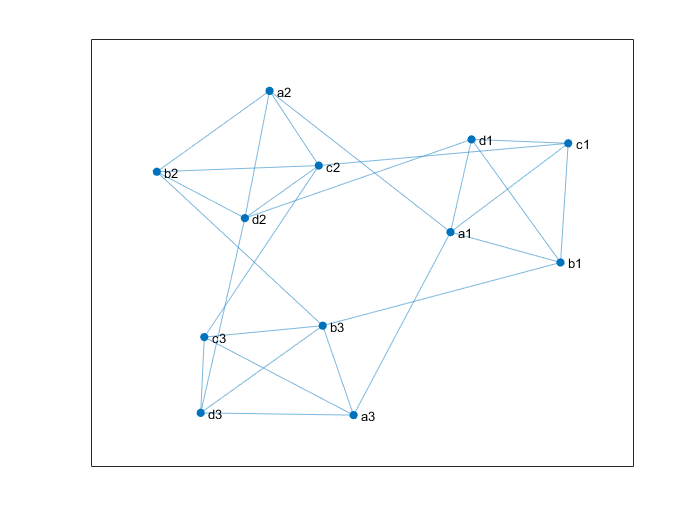

plot(G)%supra multilayer graph

N = 5;
n = 5;
m = 3;
G = generate_random_multilayer (N,n,m)

G =   graph with properties:

    Edges: [30×2 table]
    Nodes: [15×1 table]


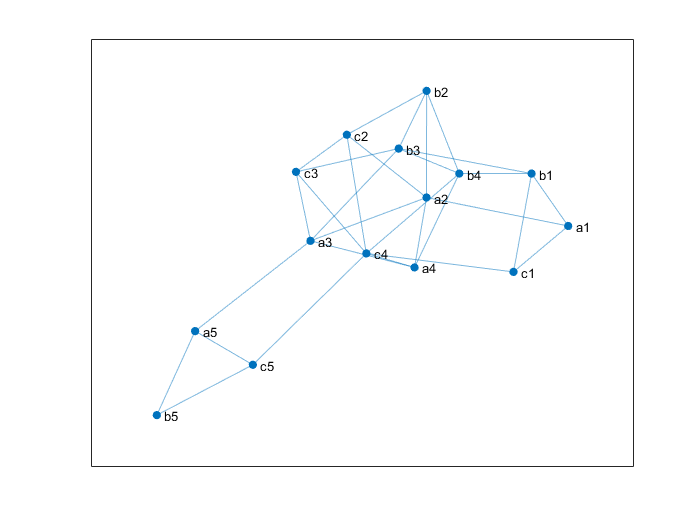

plot(G)


L1 = generate_layer(N,n) %connections of layer 1

L1 =   graph with properties:

    Edges: [10×1 table]
    Nodes: [8×0 table]


A1 = adjacency(L1); %adjaceny matrix
d = diag(ones(N,1))

d =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


L2 = generate_layer(N,n)

L2 =   graph with properties:

    Edges: [10×1 table]
    Nodes: [8×0 table]


A2 = adjacency(L2); %adjaceny matrix

supraA = zeros(N*m,N*m);
supraA(1:N,1:N) = full(A1);
supraA(N+1:2*N,N+1:N*2) = full(A2);
supraA(1:N,N+1:2*N) = d;
supraA(N+1:2*N,1:N) = d;

supraA =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     1     1     0     1     0     0     0     0     0     0
     0     0     0     1     1     1     1     0     0     0     1     0     0     0     0     0
     0     0     1     0     0     1     1     0     0     0     0     1     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     1     1     1     0     0     0     1     0     0     0     0     0     1     0     0
     0     1     1     1     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     1     0     0     1     0     0     1
     0     1     0     0     0     0     0     0     1     0     0     0     1     0     1     0


layernames = {'a', 'b', 'c', 'd', 'e', 'f', 'g', 'h'}

layernames = 1×8 cell array
    {'a'}    {'b'}    {'c'}    {'d'}    {'e'}    {'f'}    {'g'}    {'h'}


cell2mat(layernames(1))

ans = 'a'

nodenames = cell(1,N*m);

for i = 1:m
    for j = 1:N
        nodenames((i-1)*(N)+j) = {[cell2mat(layernames(i)) int2str(j)]};
    end
end
nodenames

nodenames = 1×16 cell array
    {'a1'}    {'a2'}    {'a3'}    {'a4'}    {'a5'}    {'a6'}    {'a7'}    {'a8'}    {'b1'}    {'b2'}    {'b3'}    {'b4'}    {'b5'}    {'b6'}    {'b7'}    {'b8'}


G = graph(supraA,nodenames)

G =   graph with properties:

    Edges: [28×2 table]
    Nodes: [16×1 table]


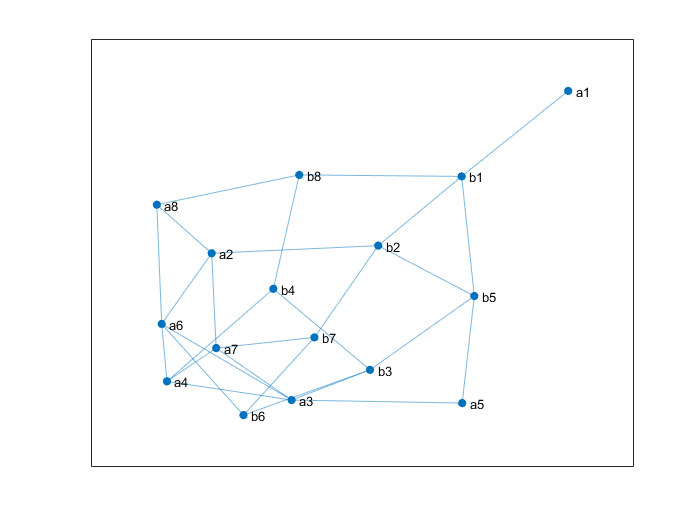

plot(G)%supra multilayer graph

### Metrics

N = 10;
n = 8;
m = 4;
G = generate_random_multilayer (N,n,m)

G =   graph with properties:

    Edges: [92×2 table]
    Nodes: [40×1 table]


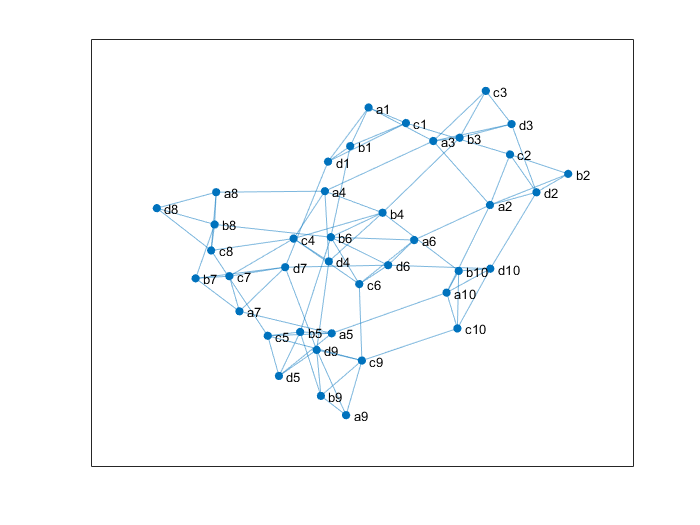

plot(G)

deg = degree(G) %degree

deg =      4
     6
     6
     5
     5
     4
     4
     4
     3
     5


std(deg)

ans = 0.9819

mean(deg)

ans = 4.6000


C = centrality(G,'Pagerank')

C =     0.0231
    0.0322
    0.0326
    0.0265
    0.0265
    0.0214
    0.0221
    0.0225
    0.0173
    0.0266


tree =   graph with properties:

    Edges: [0×1 table]
    Nodes: [1×3 table]


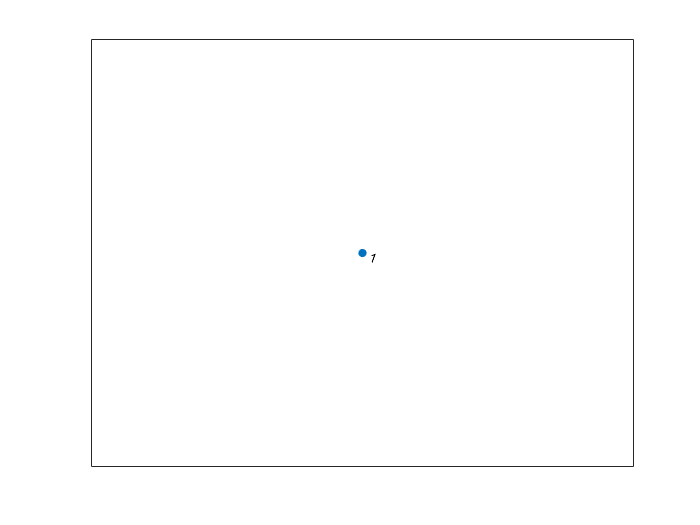


dist = distances(G);
mean(mean(dist));
conncomp(G); %groepeerd de verschillende components, als 2 stukken niet verbonden zijn zitten ze in verschillende groepen

%axflow(G)
minspantree(G)

ans =   graph with properties:

    Edges: [39×2 table]
    Nodes: [40×1 table]


%allpaths(G)
r = cyclebasis(G) 

r = 53×1 cell array
    {1×6 cell}
    {1×3 cell}
    {1×3 cell}
    {1×6 cell}
    {1×6 cell}
    {1×6 cell}
    {1×6 cell}
    {1×7 cell}
    {1×7 cell}
    {1×3 cell}
    {1×4 cell}
    {1×5 cell}
    {1×5 cell}
    {1×5 cell}
    {1×3 cell}
    {1×3 cell}


%creating the collapsed graph
N = 10;
n = 8;
m = 4;
G = generate_random_multilayer (N,n,m);
As = full(adjacency(G));
A = zeros(N,N);

for i = 1:m
    A = A + As(N*(i-1)+1 : i*N, N*(i-1)+1 : i*N);
end
gc = graph(A)

gc =   graph with properties:

    Edges: [23×2 table]
    Nodes: [10×0 table]


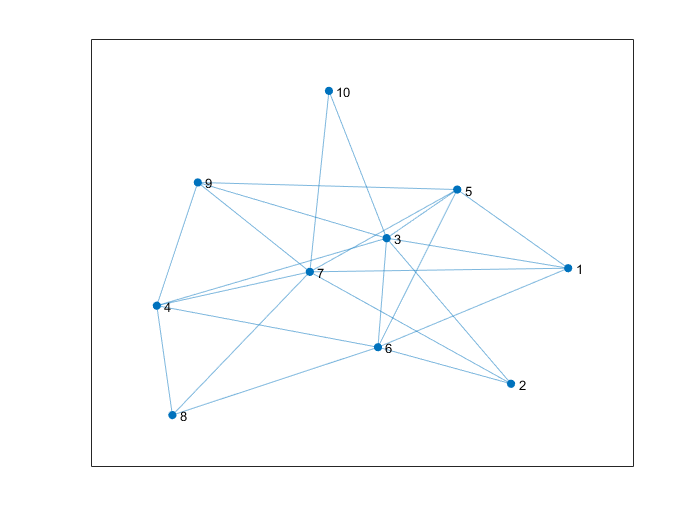

plot(gc)

cyclebasis(gc)

ans = 14×1 cell array
    {[  1 3 4 7]}
    {[    1 3 5]}
    {[    1 3 6]}
    {[  2 3 4 7]}
    {[    2 3 6]}
    {[    3 4 6]}
    {[  3 4 7 5]}
    {[3 4 7 8 6]}
    {[  3 4 7 9]}
    {[ 3 4 7 10]}
    {[  3 4 8 6]}
    {[    3 4 9]}
    {[    3 5 6]}
    {[    3 5 9]}
